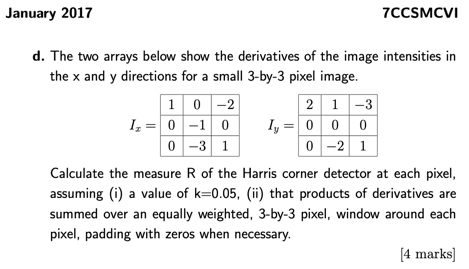

k = 0.05;

Ix = [1 0 -2
      0 -1 0
      0 -3 1];

Iy = [2 1 -3
      0 0 0
      0 -2 1];

Ix_Iy = Ix .* Iy;

Ix_2 = Ix .^2;
Iy_2 = Iy .^2;

mask = [1 1 1
        1 1 1
        1 1 1];

sum_Ix_2 = conv2(Ix_2, mask, "same");
sum_Iy_2 = conv2(Iy_2, mask, "same");
sum_Ix_Iy = conv2(Ix_Iy, mask, "same");

R = (sum_Ix_2 .* sum_Iy_2 - sum_Ix_Iy .^2) - k * (sum_Ix_2 + sum_Iy_2) .^2

R =     3.5500         0    2.7500
   15.0000   17.7500   11.0000
   -5.8000   -6.8000   -6.8000
